clear
clc

% Read in target tyre model 
target_model = (pwd, 'model_outputs', 'MATLAB_Goodyear_18.0x6.5-10_D0571');

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

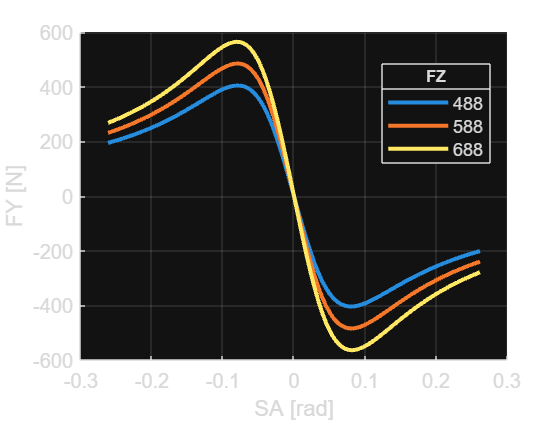

file = strcat(pwd, '\tyre_models\', target_model, '.tir');
tyre = MagicFormulaTyre(file);

% Vehicle parameters
FZ_design = 240 * 9.8 * 0.25; %2024 Design Mass = 240kg
FZ_lower = FZ_design - 100;
FZ_upper = FZ_design + 100;

% Graphing selection, 1 == plot, 0 == don't plot
graphFYSA = 1;
graphCSSA = 1;
graphMZSA = 1; % Currently producing funny results
calculateLFLSSA = 1; %Code currently not written
graphFXSR = 1;

% General form magic formula
%[FX,FY,MZ,MY,MX] = magicformula(tyre, SR, SA, FZ);


% Determine Fy with swept slip angle
if graphFYSA == 1

    % Plot FY vs SA with varied FZ
    SA = linspace(deg2rad(-15), deg2rad(15));
    SR = 0;
    figure(); grid on; hold on
    for FZ = [FZ_lower FZ_design FZ_upper]
        [FX, FY] = magicformula(tyre, SR, SA, FZ);
        plot(SA, FY, 'LineWidth', 2, 'DisplayName', num2str(FZ))
    end
    lgd = legend('Location', 'best'); xlabel('SA [rad]'); ylabel('FY [N]')
    lgd.Title.String = 'FZ'; lgd.Title.FontSize = 8;

    % % Plot FY vs SA with varied IA 
    % figure(); grid on; hold on
    % FZ = FZ_design;
    % for IA = [0 0.0349066 0.0698132] % 0, 2 and 4 degrees
    %     [FX, FY] = magicformula(tyre, SR, SA, FZ, IA);
    %     plot(SA, FY, 'LineWidth', 2, 'DisplayName', num2str(FZ))
    % end
    % legend('Location', 'best'); xlabel('SA [rad]'); ylabel('FY [N]')

end

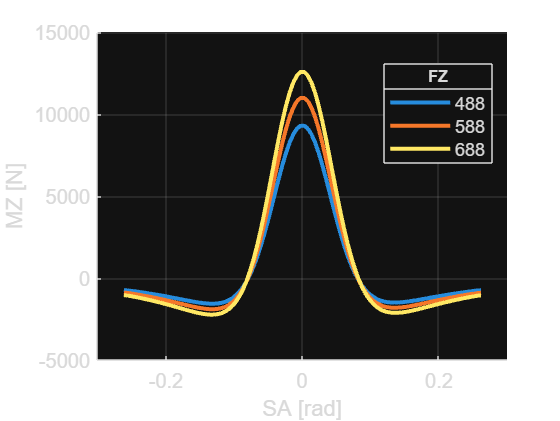



% Determine Cornering stiffness (dFy/dSA) with swept slip angle 
if graphCSSA == 1
    SA = linspace(deg2rad(-15), deg2rad(15), 100);
    SR = 0;
    figure(); grid on; hold on
    for FZ = [FZ_lower FZ_design FZ_upper]
        [FX, FY] = magicformula(tyre, SR, SA, FZ);
        cornering_stiffness = -1 * (gradient(FY(:)) ./ gradient(SA(:)));
        plot(SA, cornering_stiffness, 'LineWidth', 2, 'DisplayName', num2str(FZ))
    end
    lgd = legend('Location', 'best'); xlabel('SA [rad]'); ylabel('MZ [N]')
    lgd.Title.String = 'FZ'; lgd.Title.FontSize = 8;
end

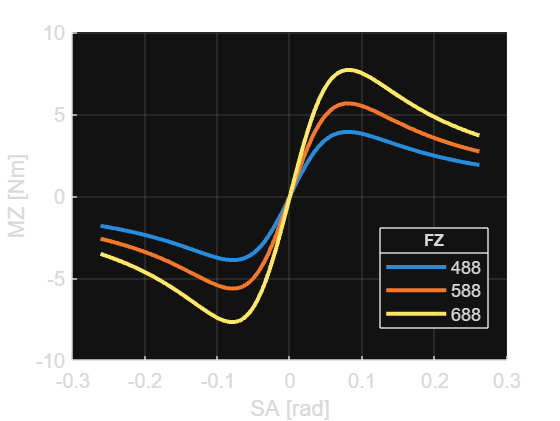


%Graph Mz vs SR %% Think model for Mz is poor? Honestly uncertain
if graphMZSA == 1
    SA = linspace(deg2rad(-15), deg2rad(15));
    SR = 0;
    figure(); grid on; hold on
    for FZ = [FZ_lower FZ_design FZ_upper]
        [FX, FY, MZ] = magicformula(tyre, SR, SA, FZ);
        plot(SA, MZ, 'LineWidth', 2, 'DisplayName', num2str(FZ))
    end
    lgd = legend('Location', 'best'); xlabel('SA [rad]'); ylabel('MZ [Nm]')
    lgd.Title.String = 'FZ'; lgd.Title.FontSize = 8;
end

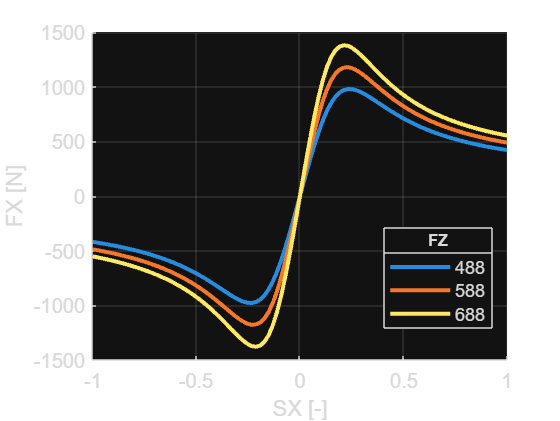


% Graph Lateral Force Load Sensitivity (LFLS) vs SA
% Replace with methodology from 
% if graphLFLSSA == 1
%     SA = linspace(deg2rad(-30), deg2rad(30), 100);
%     SR = 0;
%     LFLS = zeros(1,100);
%     Fz_low = 500;
%     [FX1, FY_low_FZ] = magicformula(tyre, SR, SA, Fz_low);
%     Fz_high = 5000;
%     [FX2, FY_high_FZ] = magicformula(tyre, SR, SA, Fz_high);
%     figure(); grid on; hold on
%     i = 1;
%     while i <= length(SA) 
%         LFLS(i) = (FY_high_FZ(i) - FY_low_FZ(i)) / FY_low_FZ(i);
%         i = i+1;
%     end
%     plot(SA, LFLS, 'LineWidth', 2)   %'DisplayName', num2str(FZ))
%     legend('Location', 'best'); xlabel('SA [rad]'); ylabel('MZ [N]')
% end
 
% Graph FX vs SR
if graphFXSR == 1
    SA = 0;
    SR = linspace(-1, 1);
    figure(); grid on; hold on
    for FZ = [FZ_lower FZ_design FZ_upper]
        FX = magicformula(tyre, SR, SA, FZ);
        plot(SR, FX, 'LineWidth', 2, 'DisplayName', num2str(FZ))
    end
    lgd = legend('Location', 'best'); xlabel('SX [-]'); ylabel('FX [N]')
    lgd.Title.String = 'FZ'; lgd.Title.FontSize = 8;
end